# Brake-Reuß Beam - DIC data

We consider digital image correlation measurements from a shaker ringdown test on a beam with a bolted lap joint [1,2]. Oscillations are initialized close to its slowest 2D spectral submanifold (SSM), which will be identified and used for model reduction.

The dataset contains the displacement field (206 points in 720 mm of beam length) of the bottom beam side measured via DIC and accelerations measured via accelerometers (ACC) in 2 locations. All data refers to a single experimental trial, acquired with different measurement devices (as described in [1]). The dataset also includes backbone curves results obtained using the Peak Finding and Fitting (PFF) method based on accelerometer signals. 

Here we construct a reduced-order model using DIC data and we validate it on the acceleration signals.

[1] W. Chen, D. Jana, A. Singh, M. Jin, M. Cenedese, G. Kosova, M. W. R. Brake, C. W. Schwingshackl, S. Nagarajaiah, K. Moore, and J. P. Noël. Measurement and identification of the nonlinear dynamics of a jointed structure using full-field data; Part I - Measurement of nonlinear dynamics. *Mechanical Systems and Signal Processing*, 166:108401, 2022. [https://doi.org/10.1016/j.ymssp.2021.108401](https://doi.org/10.1016/j.ymssp.2021.108401)

[2] M. Jin, G. Kosova, M. Cenedese, W. Chen, D. Jana, A. Singh, M. W. R. Brake, C. W. Schwingshackl, S. Nagarajaiah, K. Moore, and J. P. Noël. Measurement and identification of the nonlinear dynamics of a jointed structure using full-field data; Part II - Nonlinear system identification. *Mechanical Systems and Signal Processing*, 166:108402, 2022. [https://doi.org/10.1016/j.ymssp.2021.108402](https://doi.org/10.1016/j.ymssp.2021.108402)

clearvars
close all

## Experimental Data

We will divide the data into a training set, for model fitting, and a test set, for validation. In this case the experimental data consists of a single trajectory, with different measruements. We train on DIC data and validate on acceleration data.

load data.mat

data_BRB

data_BRB = struct with fields:
            TimeDIC: [15260×1 double]
    DisplacementDIC: [206×15260 double]
            TimeACC: [-30.257 -30.257 -30.256 -30.256 -30.256 -30.256 -30.256 -30.256 -30.255 -30.255 -30.255 -30.255 -30.255 -30.255 -30.255 -30.254 -30.254 -30.254 -30.254 -30.254 -30.254 -30.253 -30.253 -30.253 -30.253 -30.253 -30.253 -30.253 … ]
    AccelerationACC: [2×272128 double]
              Xmesh: [3.2361 6.6309 10.026 13.42 16.815 20.21 23.605 26.999 30.394 33.789 37.184 40.578 43.973 47.368 50.763 54.157 57.552 60.947 64.342 67.736 71.131 74.526 77.921 81.315 84.71 88.105 91.5 94.894 98.289 101.68 105.08 108.47 111.87 … ]
              Units: [1×1 struct]
        LocationACC: [2×1 double]
      PFFResultsACC: [1×1 struct]


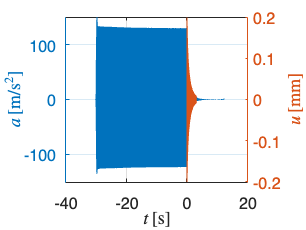


% Store data
Xmesh = data_BRB.Xmesh;
% Displacements
uData = cell(1,2);
uData{1,1} = data_BRB.TimeDIC;
uData{1,2} = data_BRB.DisplacementDIC;
% Accelerations
aData{1,1} = data_BRB.TimeACC;
aData{1,2} = data_BRB.AccelerationACC;

% Plot data: acceleration & displacements
customFigure;
yyaxis left
plot(aData{1,1}, aData{1,2}(2,:))
ylabel('acceleration [m/s^2]'); ylim([-1 1]*max(abs(aData{1,2}(2,:))))
xlabel('$t \, [$s$]$','interpreter','latex');  
ylabel('$a \, [$m/s$^2]$','interpreter','latex'); 
yyaxis right
plot(uData{1,1}, uData{1,2}(183,:));  ylim([-1 1]*max(abs(uData{1,2}(183,:))))
ylabel('$u \, [$mm$]$','interpreter','latex'); 

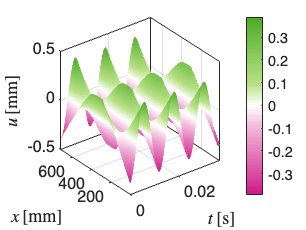

customFigure;
map = pinkgreen(101);
[TT,XX] = meshgrid(uData{1,1},Xmesh);
surf(TT,XX,uData{1,2})
xlabel('$t \, [$s$]$','interpreter','latex'); 
ylabel('$x \, [$mm$]$','interpreter','latex'); 
zlabel('$u \, [$mm$]$','interpreter','latex'); 
shading  interp
colormap(map)
colorbar
xlim([0 1/80*3]+uData{1,1}(1))
ylim([Xmesh(1) Xmesh(end)])
view(3)

## Delay embedding

To diversify the data, we augment displacements with four delayed measurements, which will be also useful for recovering velocity and acceleration fields later.

overEmbed = 5;
SSMDim = 2;

yData = coordinatesEmbedding(uData, SSMDim, 'OverEmbedding', overEmbed);

The 1236 embedding coordinates consist of the 206 measured states and their 5 time-delayed measurements.


## Datadriven manifold fitting

The measured trajectories are assumed to lie close to a two-dimensional manifold that is tangent at the origin to the eigenspace corresponding to the slowest pair of eigenvalues. We now want to fit a polynomial of order $M$ to the data points to approximate the manifold. Here we use a graph style parametrization, meaning that the manifold is parametrized using coordinates in the computed eigenspace $V_e$. This excludes the possibility of folds on the manifold (however, if necessary we may circumvent this problem by increasing the dimensionality of the observed space). 

 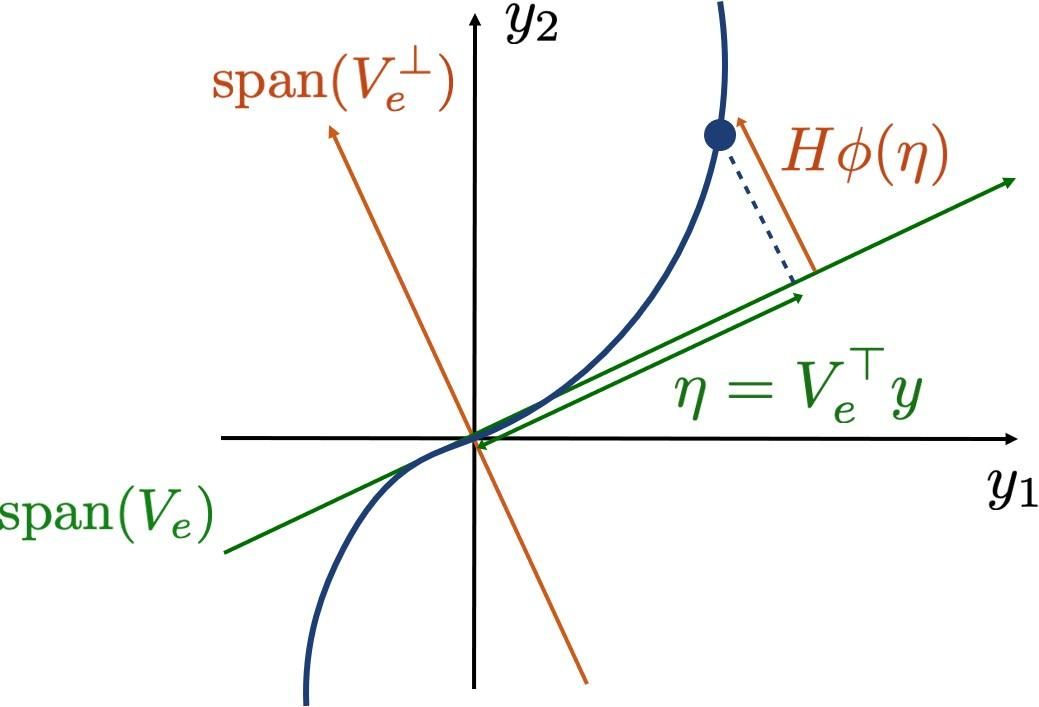

We seek the $2N\times m_M$ polynomial coefficient matrix $H$ of the manifold on the form

$y = V_e V_e^\top y + H \phi_{m,2:M}(V_e^\top y) $,

where the function $\phi_{m,2:M}(q)$ computes a vector of all $m_M$ monomials from orders 2 up to $M$ of an $m$-vector $q$. This optimization problem amounts to minimizing a cost function computed from the measured data $y_k$,


$$C_r(V_e,H) = \sum_{k=1}^N ||y_k - V_eV_e^\top y_k - H\phi_{m,2:M}(V_e^\top y_k) ||$$


to find $H$ and the $2N\times 2$ eigenspace matrix $V_e$, under the constraints that $V_e^\top H=0$ and $V_e^\top V_e = I$. The minimization is performed with the Matlab function `fmincon` in `IMparametrization`. In this case, we set $M=1$, so that our manifold is the plane spanned by the 2 most relevant directions of the Principal Component Anlysis of data.

SSMOrder = 1;
[IMInfo, SSMChart, SSMFunction] = IMGeometry(yData, SSMDim, SSMOrder);

## Plot and validation

Now that we have computed the eigenspace of the manifold, we pass to the reduced coordinates $y$ by projecting all trajectories onto the eigenspace. 

etaData = projectTrajectories(IMInfo, yData);

We plot the test and training set trajectories projected onto the plane $$V$$.

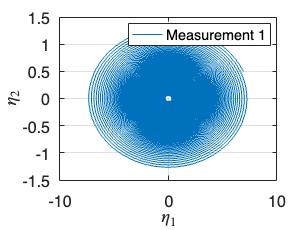

plotReducedCoordinates(etaData);

Furthermore, we draw the first component of the manifold shape along with the trajectory from the training set. 

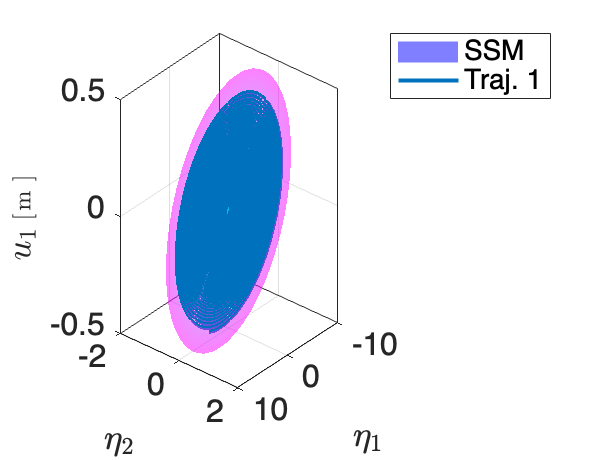

outdof = 1;
plotSSMandTrajectories(IMInfo, outdof, yData, etaData)
view(-230,20); zlabel('$u_1 \, [$m$]$','Interpreter','latex')

## Reduced order model

We compute a model for the reduced dynamics with the truncated training data projected onto the manifold. The function `IMDynamicsFlow` fits a polynomial map


$$\dot{\eta} = W_r \phi(\eta)$$


where $\phi(\eta)$ again computes a vector of all monomials of $\eta$, and $W_r$ is a matrix of polynomial coefficients. 

We are also specifying that we want the reduced dynamics on a normal form, and seek the Taylor expansion of a map $N$ fulfilling


$$\dot{z} = N(z) = Dz + W_n\phi(z)$$


with $D$ a diagonal matrix and $W_n$ containing coefficients for the near-resonant nonlinear terms, after a near-identity change of coordinates


$$z = T^{-1}(\eta) = \eta + W_t \phi(\eta)$$


with $W_t$ containing the coefficients for the nonlinear terms of the coordinate change.

The optimization is performed in `IMDynamicsFlow` with the Matlab function `fminunc`. We apply a regularization on the polynomial coefficients to prevent overfitting. The regularization parameter is optimized from a logarithmic range of values with ridge regression. 

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1         0.286682                          16.3
     1           4        0.0959592     0.00122636           12.7  
     2           6        0.0829207       0.147846          0.977  
     3           7        0.0825095              1          0.979  
     4           8        0.0820495              1          0.492  
     5           9        0.0816302              1          0.489  
     6          10        0.0801643              1            1.3  
     7          12        0.0791611       0.352853           2.55  
     8          13        0.0745167              1           3.62  
     9          14        0.0670175              1           3.84  
    10          15        0.0447264              1           3.18  
    11          16

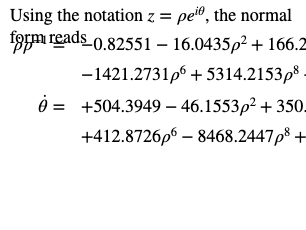

ROMOrder = 11;
Nfolds = 5;
Nregvals = 30; 
RDInfo = IMDynamicsFlow(etaData, 'R_PolyOrd', ROMOrder, 'n_folds', Nfolds, 'l_vals', logspace(-6,0,Nregvals), 'style', 'normalform');

We transform the truncated initial condition of our test trajectory according to the obtained change of coordinates, and integrate our reduced order evolution rule to predict the development of the trajectory. 

[yRec, etaRec, zRec] = advect(IMInfo, RDInfo, yData);

## Evaluation of reduced dynamics

The error NMTE is computed as the average distance of the predicted trajectories to the measured ones in the observable space.

normedTrajDist = computeTrajectoryErrors(yRec, yData);
NMTE = mean(normedTrajDist)*100

NMTE =       0.90285


We plot the measured test set trajectory in the reduced coordinates and compare it to the prediction. 

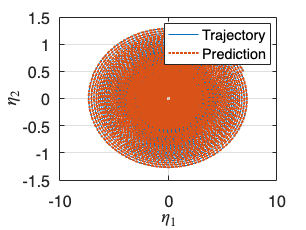

plotReducedCoordinates(etaData, etaRec)
legend({'Trajectory', 'Prediction'})

We also plot the measured and predicted displacement of the first DIC point.

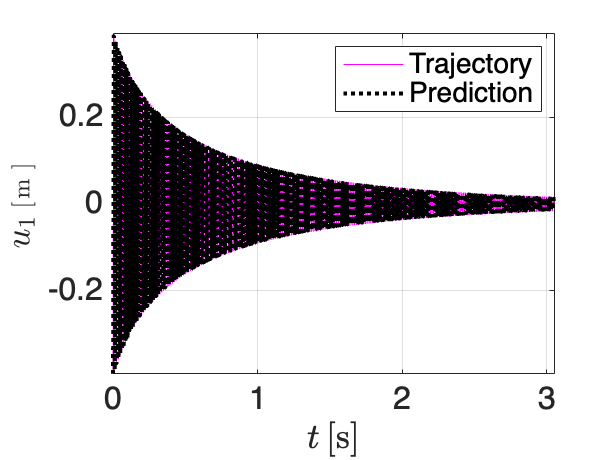

plotTrajectories(yData, yRec, 'm','PlotCoordinate', outdof)
legend({'Trajectory', 'Prediction'})
xlabel('$t \, [$s$]$','interpreter','latex');
ylabel('$u_1 \, [$m$]$','Interpreter','latex')

## Energy as amplitude metric

In our delay-embedding space, we can define numerical differentiation on a state vector. Therefore, we can compute velocities as central differences and compute the kinetic energy of the beam, which is defined as our amplitude metric.

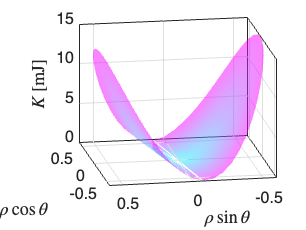

nDisplacements = size(uData{1,2},1);
samplingTime = uData{1,1}(2)-uData{1,1}(1);
amplitudeFunction = @(y) mean( ( (y([1:nDisplacements]+2*nDisplacements,:)-y([1:nDisplacements],:))/2/samplingTime).^2)*1.796/2*1e-3; % energy in [mJ]
% Plot SSM with the kinetic energy
plotSSMandTrajectories(IMInfo, amplitudeFunction, yData, zRec, 'NFT', RDInfo.transformation.map)
view(-100,20); legend('off')
zlabel('$K \, [$mJ$]$','Interpreter','latex'); 

## Backbone curves

With the knowledge of the coefficients of the normal form, we extract backbone curves for the instantaneous damping and frequency. The instantaneous damping is strongly nonlinear, but the frequency remains virtually unchanged in our model.

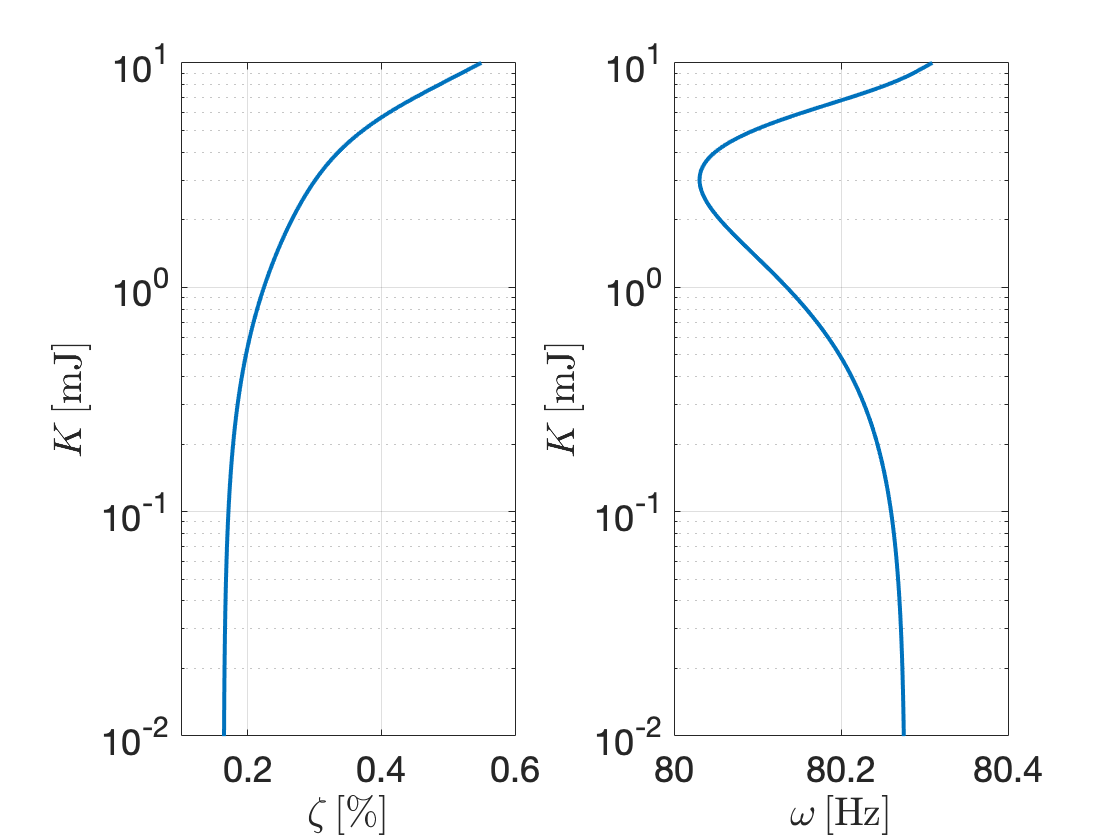

zData = transformTrajectories(RDInfo.inverseTransformation.map, etaData);
rhoMax = abs(zData{1,2}(1,1));
BBCInfo = backboneCurves(IMInfo, RDInfo, amplitudeFunction, rhoMax,'Hz');
subplot(121); 
xlabel('$\zeta \, [$\%$]$','Interpreter','latex');
ylabel('$K \, [$mJ$]$','Interpreter','latex'); 
xlim([0.1 0.6]); ylim([0.01 10])
set(gca,'yscale','log')
subplot(122); 
xlabel('$\omega \, [$Hz$]$','Interpreter','latex');
ylabel('$K \, [$mJ$]$','Interpreter','latex'); 
xlim([80 80.4]); ylim([0.01 10])
set(gca,'yscale','log')

## Validation with Accelerations

We now validate our model using the accelerometer data, and the identication results of backbone curves via Peak Finding and Fitting, reported on [2] above.

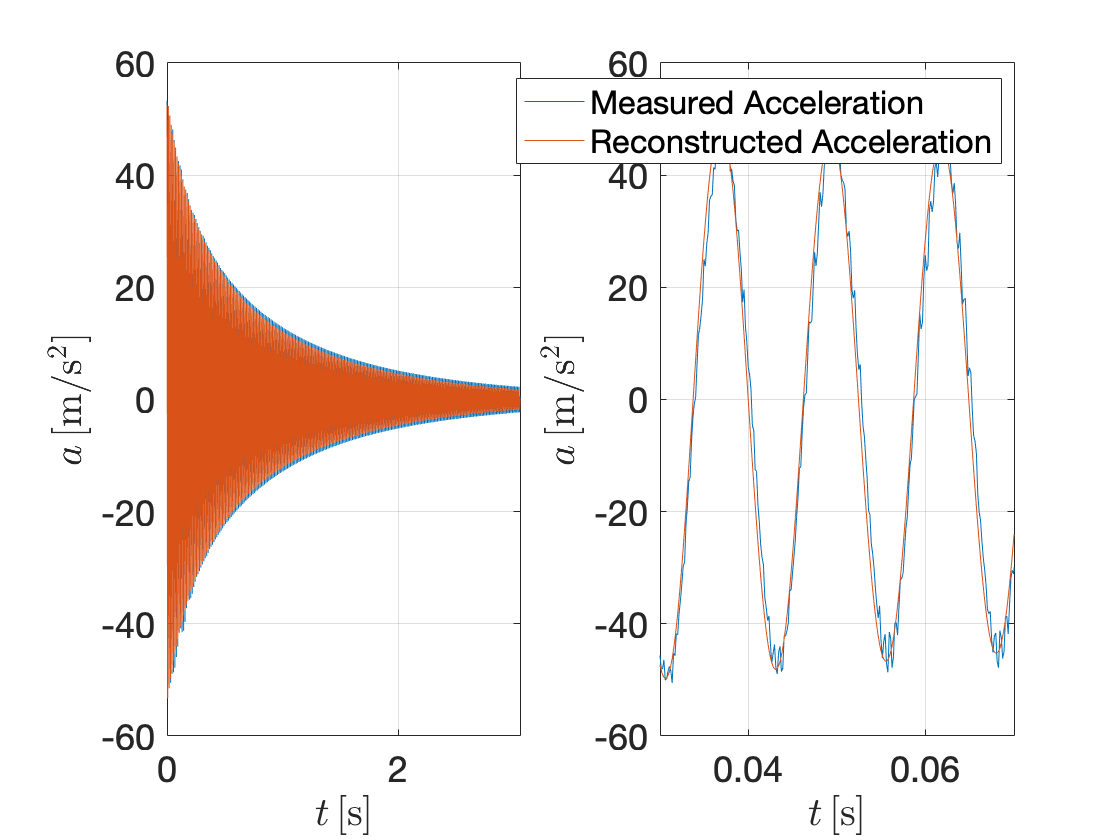

% Select Accelerometer Location
idx_acc = 1;
aData{1,1} = data_BRB.TimeACC;
aData{1,2} = data_BRB.AccelerationACC;
% Linear Interpolation among nodes
tAcc = aData{1,1}; aAcc = aData{1,2}(idx_acc,:); 
loc_acc = data_BRB.LocationACC(idx_acc);
idxs_acc_DIC =sum(Xmesh<loc_acc)+[0 1];
% Define accelerations
accelerationFunctions = @(y) 1e-3*(y([1:nDisplacements]+2*nDisplacements,:)-2*y([1:nDisplacements]+nDisplacements,:)+y([1:nDisplacements],:))/samplingTime.^2; % accelerations in [m/s^2]
accelerationFunction = @(a) (a(idxs_acc_DIC(2),:)-a(idxs_acc_DIC(1),:))*(loc_acc - Xmesh(idxs_acc_DIC(1)))/(Xmesh(idxs_acc_DIC(2)) - Xmesh(idxs_acc_DIC(1))) + a(idxs_acc_DIC(1),:);
tRec = yRec{1,1};
aRec = accelerationFunction( accelerationFunctions (yRec{1,2}));
% Plot results
customFigure('subPlot',[1 2]); subplot(121);
plot(tAcc,aAcc,tRec,aRec)
xlim([tRec(1) tRec(end)])
xlabel('$t \, [$s$]$','interpreter','latex'); 
ylabel('$a \, [$m/s$^2]$','interpreter','latex'); 
xlim([tRec(1) tRec(end)])
subplot(122);
plot(tAcc,aAcc,tRec,aRec)
xlabel('$t \, [$s$]$','interpreter','latex'); 
legend('Measured Acceleration','Reconstructed Acceleration')
ylabel('$a \, [$m/s$^2]$','interpreter','latex'); 
xlim([0.03 0.07])

accelerationError = sqrt(mean( (aRec - interp1(tAcc,aAcc,tRec)).^2 ))/max(abs(aRec))*100

accelerationError =        3.8439


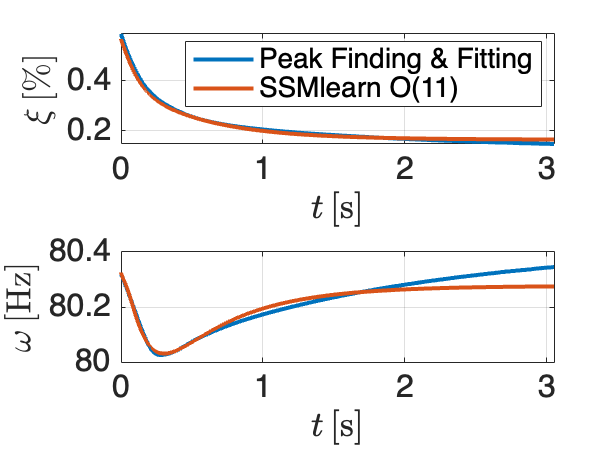

% Instantaneous damping and frequency in time
instDamping = RDInfo.conjugateDynamics.damping(abs(zRec{1,2}(1,:)));    
instFrequency = RDInfo.conjugateDynamics.frequency(abs(zRec{1,2}(1,:)));  
instDampingRatio = -instDamping./instFrequency*100;   
customFigure('subPlot',[2 1]);
subplot(211);
plot(data_BRB.PFFResultsACC.Time(idx_acc,:),data_BRB.PFFResultsACC.Damping(idx_acc,:)*100,'Linewidth',2,'DisplayName','Peak Finding & Fitting')
plot(tRec,instDampingRatio,'Linewidth',2,'DisplayName',['SSMlearn O(' num2str(ROMOrder) ')'])
xlabel('$t \, [$s$]$','interpreter','latex'); 
ylabel('$\xi \, [$\%$]$','interpreter','latex'); 
legend
xlim([tRec(1) tRec(end)])
subplot(212);
plot(data_BRB.PFFResultsACC.Time(idx_acc,:),data_BRB.PFFResultsACC.Frequency(idx_acc,:),'Linewidth',2,'DisplayName','PFF')
plot(tRec,instFrequency/2/pi,'Linewidth',2,'DisplayName','SSMlearn')
xlabel('$t \, [$s$]$','interpreter','latex'); 
ylabel('$\omega \, [$Hz$]$','interpreter','latex');
xlim([tRec(1) tRec(end)])